
% Load and plot original data
clear all
clf
load Q1data

%%% Your code to compute YQ1est should go below
deg =  3; % Degree
powers=0:deg;
YQ1est = zeros(size(YQ1data))

YQ1est =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


A = PolynomialMatrix(XQ1data,deg)

A =     1.0000         0         0         0
    1.0000    0.0125    0.0002    0.0000
    1.0000    0.0251    0.0006    0.0000
    1.0000    0.0376    0.0014    0.0001
    1.0000    0.0501    0.0025    0.0001
    1.0000    0.0627    0.0039    0.0002
    1.0000    0.0752    0.0057    0.0004
    1.0000    0.0877    0.0077    0.0007
    1.0000    0.1003    0.0101    0.0010
    1.0000    0.1128    0.0127    0.0014


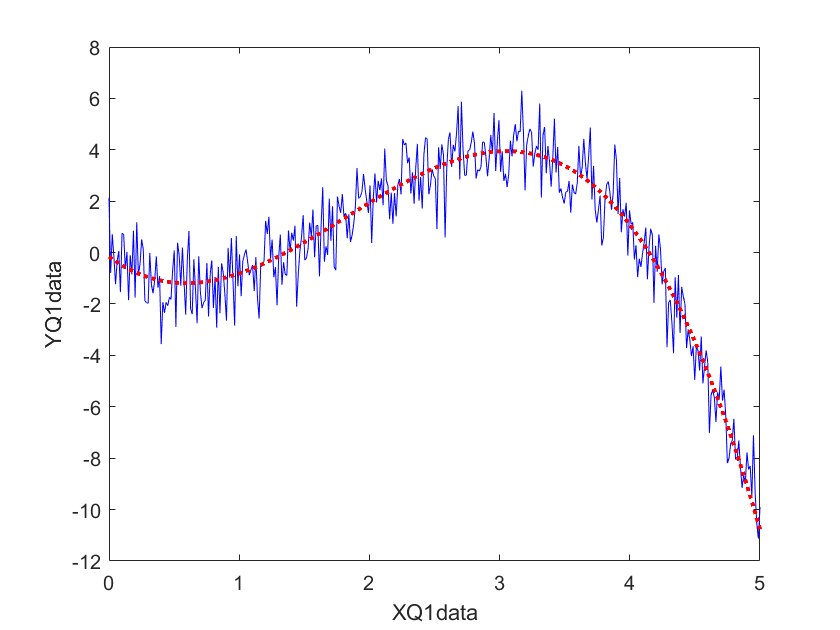


% Compute the coefficients 
[Q,R] = qr(A);
Ar = (Q*R)\YQ1data';

for I = 1:length(powers)
    YQ1est = YQ1est + Ar(I)*XQ1data.^powers(I);
end

% Plot the results of your estimate and compare to original data
% The code below assumes you have already computed YQ1est 
plot(XQ1data,YQ1data,'b')
xlabel('XQ1data')
ylabel('YQ1data')
hold on
plot(XQ1data,YQ1est,'r:','LineWidth',2)

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
 powers=0:n; 
     for I = 1:length(powers)
         M(:,I)=x.^powers(I);
     end
end